# Transient 2D diffusion

clearvars;
close all;
clc

## Discretization in space

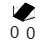

L = 2 * pi;
N = 30;
h = L/(N-1); % Grid spacing
[x,y] = meshgrid(0:h:L, 0:h:L); % coordinates of grid points
[K,J] = size(x); % number of grid points in each direction
M = J*K; % total number of grid points

D2 = Laplacian(h,h,J,K); % Discrete Laplace operator
q = zeros(M,1); % Zero source term

% Boundary conditions
iL = find(x==0); iR = find(x==L); 
iT = find(y==L); iB = find(y==0);

% [D2,q] = NeumannBC(D2,q,iT, 1,0,h);
% [D2,q] = NeumannBC(D2,q,iB,-1,0,h);
% [D2,q] = NeumannBC(D2,q,iL,-1,0,h);
% [D2,q] = NeumannBC(D2,q,iR,1,0,h);

% Dirichlet BCs
% D2(iL,:) = 0; q(iL) = 0;
% D2(iR,:) = 0; q(iR) = 0;
% D2(iT,:) = 0; q(iT) = 0;
% D2(iB,:) = 0; q(iB) = 0;

% [D2,q] = NeumannBC(D2,q,iT, 1,0,h);
% [D2,q] = NeumannBC(D2,q,iB,-1,0,h);

% Dirichlet BCs
D2(iL,:) = 0; q(iL) = 0;
D2(iR,:) = 0; q(iR) = 0;
D2(iT,:) = 0; q(iT) = 0;
D2(iB,:) = 0; q(iB) = 0;


% Config
kappa = 1e-2;
s = 1/4;
dt = s*h^2/kappa;
t_end = 500;

I = speye(M);
R = I + kappa*dt*D2;
b = dt*q;


kx = 0.5; ky = 0.5;


% T_ini = sin(kx*x).*cos(ky*y);
T_ini = x;
surf(x,y,T_ini)

## explicit Euler


T = T_ini(:);

for t = dt:dt:t_end
    T = R*T + b;
    %T = T + dt*D2*T + dt*q;
end
surf(x,y,reshape(T,K,J));

## Implicit Euler

L = I - kappa*dt*D2;
T = T_ini(:);
for t = dt:dt:t_end
    T = L\(T+b);
end
surf(x,y,reshape(T,K,J));

function D2 = Laplacian(dx,dy,J,K)
    M = J*K;
    e = ones(M,1);
    D2x = 1/dx^2 *spdiags([1,-2,1].*e,[-K,0,K],M,M);
    D2y = 1/dy^2 *spdiags([1,-2,1].*e,[-1,0,1],M,M);
    D2 = D2x+D2y;
end

function [D2,q] = NeumannBC(D2,q,ib,ig,beta,dx)
    for i = ib(:)'
        D2(i,i-ig) = D2(i,i-ig) + D2(i-ig,i);
        q(i) = q(i) + D2(i-ig,i)*beta*2*dx;
        
        if i+ig>0 && i+ig<=size(D2,2)
            D2(i,i+ig) = 0;
        end
        
    end
end